# 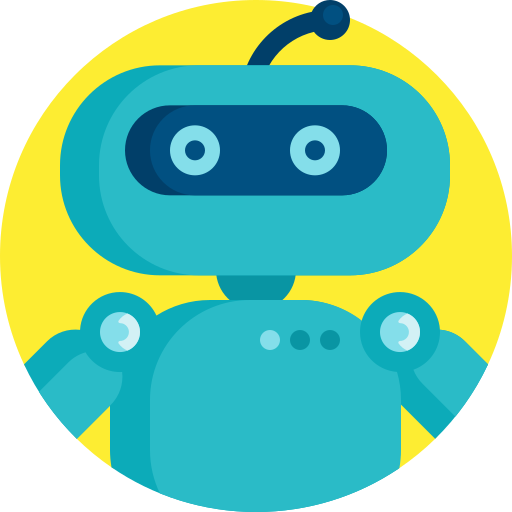

# **MEC4127F: Introduction to Robotics**

# Chapter 10: Attitude control design for quadcopters

## 10.1 Introduction

**Chapter 9** provided an overview of the dynamic model of an idealised quadcopter. This included defining the rotational and translational dynamics of the UAV. **Chapter 10** will now make use of the rotational dynamic models to inform control design of the body-frame roll, pitch, and yaw channels.

In the case of classical control theory, it is common practice to design two separate controllers — one for the rotational system, and one for the translational system. Because the quadcopter is only able to traverse in the $\hat{\bf x}_B$-$\hat{\bf y}_B$ plane as a result of a roll or pitch motion, the attitude controller can be thought of an inner loop, with the translational controller considered as the outer loop. This is often referred to as a cascaded control scheme. Figure 10.1 gives a high-level illustration of this concept.

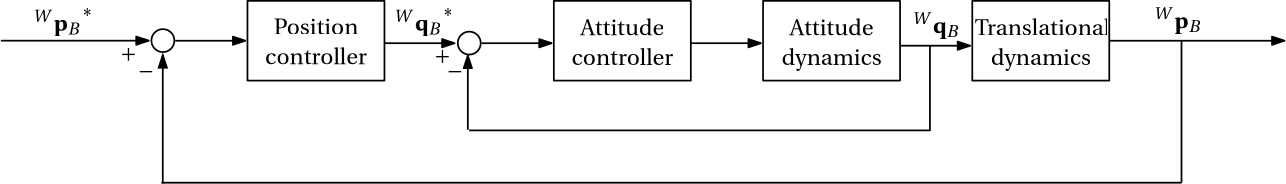

**Figure 10.1:** High-level block diagram of cascaded control scheme.

We will work towards implementing the control strategy depicted in the figure above over the course of **Chapter 10 **and **Chapter 11**, but we first have to define several key elements to the control system, namely:

- **control allocation** — mapping desired thrust and torque vectors to the rotor speeds;

- **dynamic analysis** — assessing the dynamics of the system in order to inform an appropriate flight envelope;

- **attitude control design** — design a controller that can stabilise the orientation of the quadcopter whilst also meeting the prescribed specifications;

- **thrust vectoring **— relate the position control command to the orientation error in order to dictate orientation changes required;

- **position control design** — design a controller that can stabilise the translation of the quadcopter whilst also meeting the prescribed specifications;

## 10.2 Control allocation

Recall that the controllable torque vector was derived to be


$${^B{\bf m}}= \left[\begin{array}{cccccccc}    lk_f\left(\overline\omega^2_4-\overline\omega^2_2\right) \\    lk_f\left(\overline\omega^2_3-\overline\omega^2_1\right) \\ k_\tau(\left(\overline\omega_1^2-\overline\omega_2^2+\overline\omega_3^2-\overline\omega_4^2\right) \end{array}\right],$$


where $l$ is the distance from the centre of mass to each motor shaft, $k_f$ is the thrust coefficient, and $\overline\omega_i$ is the angular velocity of rotor $i$. Additionally, the net thrust produced by all four rotors was shown to be


$$\begin{array}{ll}
f_\Sigma 
&=& k_f\sum_{i=1}^4\overline\omega^2_i.\\
\end{array}$$


As we will show later in this Chapter, the torque vector will be used to control the orientation of the quadcopter. The net thrust will be used to control the heave of the platform, which we will make use of in **Chapter 11**. Together, these two quantities will also be used to dictate translational motion of the quadcopter. For this reason, $^B{\bf m}^*$ and $f_\Sigma^*$ will be thought of as *virtual control inputs*, similar to how $\{v^*,\dot\psi^*\}$ were virtual control signals when handling the differentially-steered robot.

As with the wheeled robot control, we also need to be able to map from the virtual control signals to the low-level actuator signals — that being the motor speeds. In other words, we require a mapping: $\{f_\Sigma^*,{^B{\bf m}^*\}\rightarrow \{\overline\omega^*_1,\overline\omega^*_2,\overline\omega^*_3,\overline\omega^*_4\}$. Combining the two equations above into a single matrix yields


$$ \left[\begin{array}{cccccccc} f_\Sigma \\{^B{\bf m}}  \end{array}\right]
=\left[\begin{array}{cccccccc} f_\Sigma \\m_x \\m_y\\m_z  \end{array}\right]
= \left[\begin{array}{cccccccc}   
k_f & k_f & k_f & k_f\\
0 & -lk_f & 0 & lk_f \\
-lk_f &0 & lk_f & 0\\
k_\tau & -k_\tau & k_\tau & -k_\tau 
\end{array}\right]
\left[\begin{array}{cccccccc} \overline\omega_1^2 \\ \overline\omega_2^2 \\ \overline\omega_3^2 \\ \overline\omega_4^2 \end{array}\right].$$


Assuming our controller prescribes desired torque and thrust values of $\{f_\Sigma^*,{^B{\bf m}^*\}$, we can invert the relationship above to determine the desired rotor speeds, which is given by


$$\begin{array}{ll}
\left[\begin{array}{cccccccc} \overline\omega_1^2 \\ \overline\omega_2^2 \\ \overline\omega_3^2 \\ \overline\omega_4^2 \end{array}\right] ^*

&=& \left[\begin{array}{cccccccc}   
k_f & k_f & k_f & k_f\\
0 & -lk_f & 0 & lk_f \\
-lk_f &0 & lk_f & 0\\
k_\tau & -k_\tau & k_\tau & -k_\tau 
\end{array}\right]^{-1}\left[\begin{array}{cccccccc} f^*_\Sigma \\{^B{\bf m}^*}  \end{array}\right],\\
&=& \left[\begin{array}{cccccccc}   
\frac{1}{4k_f} & 0 & -\frac{1}{2lk_f} & \frac{1}{4k_\tau}\\
\frac{1}{4k_f} & -\frac{1}{2lk_f} & 0 & -\frac{1}{4k_\tau} \\
\frac{1}{4k_f} &0 & \frac{1}{2lk_f} & \frac{1}{4k_\tau}\\
\frac{1}{4k_f} & \frac{1}{2lk_f} & 0 & -\frac{1}{4k_\tau} 
\end{array}\right]\left[\begin{array}{cccccccc} f_\Sigma^* \\{^B{\bf m}^*}  \end{array}\right].\\
\end{array}$$


syms kf kt l positive
A = [kf    kf   kf   kf;
     0  -l*kf    0 l*kf;
     -l*kf  0 l*kf    0;
     kt   -kt   kt  -kt];
inv(A)

$$ans = \left(\begin{array}{cccc} \frac{1}{4\,\mathrm{kf}} & 0 & -\frac{1}{2\,\mathrm{kf}\,l} & \frac{1}{4\,\mathrm{kt}}\\ \frac{1}{4\,\mathrm{kf}} & -\frac{1}{2\,\mathrm{kf}\,l} & 0 & -\frac{1}{4\,\mathrm{kt}}\\ \frac{1}{4\,\mathrm{kf}} & 0 & \frac{1}{2\,\mathrm{kf}\,l} & \frac{1}{4\,\mathrm{kt}}\\ \frac{1}{4\,\mathrm{kf}} & \frac{1}{2\,\mathrm{kf}\,l} & 0 & -\frac{1}{4\,\mathrm{kt}} \end{array}\right)$$

The matrix mapping above will be very useful when we begin to define our controllers and need to determine the rotor speeds required to produce the required rigid-body thrust and torque. Notably, the matrix operation above returns the *squared* rotor speeds that are required. Naturally, we would have to square-root each element to obtain the desired rotors speeds. We must also not forget that are we are assuming that the desired and actual rotor speeds are related by


$$\overline\omega_i(s)=\overline\omega_i^*(s)e^{-st_d},$$


where $t_d$ is a fixed delay period.

## 10.3 Analysis of attitude dynamics

In **Chapter 9** we presented the rigid-body orientation dynamics of the quadcopter as


$${\bf J}{^B\dot{\bf \omega}}+{^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right) = {^B{\bf m}},$$


where ${\bf J}$ is a diagonal inertia matrix given by


$${\bf J}=\left[\begin{array}{cc}
J_{xx} & 0 & 0 \\
0 & J_{yy} & 0 \\
0 & 0 & J_{zz}
\end{array}\right],$$


${^B{\bf \omega}}$ describes the angular velocity of the rigid body in $\{B\}$, and ${^B{\bf m}}$ is the applied torque vector in $\{B\}$. The second term in the dynamic equation above, namely ${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)$, is referred to as the centripetal moment and arises because we are describing the dynamics in $\{B\}$, which is a non-inertial reference frame. We can further assess this term by writing it out in its explicit form:


$${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)=\left[\begin{array}{cc}
\omega_y\omega_z\left(J_{zz} -J_{yy} \right) \\
\omega_x \omega_z\left(J_{xx}   -J_{zz} \right) \\
\omega_x \omega_y\left(J_{yy}  -J_{xx} \right) 
\end{array}\right],$$


where


$${^B{\bf\omega}}=\left[\begin{array}{cc}
\omega_x & \omega_y & \omega_z
\end{array}\right]^T.$$


syms w_x w_y w_z J_x J_y J_z positive
w = [w_x w_y w_z]';
J = diag([J_x,J_y,J_z]);
m_cent = cross(w,J*w)

$$m\_cent = \left(\begin{array}{c} J_{z}\,w_{y}\,w_{z}-J_{y}\,w_{y}\,w_{z}\\ J_{x}\,w_{x}\,w_{z}-J_{z}\,w_{x}\,w_{z}\\ J_{y}\,w_{x}\,w_{y}-J_{x}\,w_{x}\,w_{y} \end{array}\right)$$

The implication of this term is that if there is rotational motion in at least two channels, such as $\omega_y$ about $\hat{\bf y}_B$ and $\omega_z$ about $\hat{\bf z}_B$, then this will result in a centripetal coupling moment about $\hat{\bf x}_B$ as a result of $\omega_y\omega_z\left(J_{zz} -J_{yy} \right)$. This type of effect is undesirable, as we ideally do not want any coupling between any two axes, as it makes for a more challenging control design procedure. We therefore want to ideally make design choices such that ${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)\approx 0$.

Quadcopters are usually designed such that $J_{xx}\approx J_{yy}$, which suggests that the centripetal moment reduces to


$${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)=\left[\begin{array}{cc}
\omega_y\omega_z\left(J_{zz} -J_{yy} \right) \\
\omega_x \omega_z\left(J_{xx}   -J_{zz} \right) \\
0
\end{array}\right].$$


Additionally, if we are able to regulate the rotation of the quadcopter body about $\hat{\bf z}_B$ such that $\omega_z\approx 0$, this would then imply that


$${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)\approx 0,$$


which would remove the centripetal coupling from the attitude dynamics, thereby leaving the simplified form of


$${\bf J}{^B\dot{\bf \omega}}\approx {^B{\bf m}}.$$


As $\bf J$ is a diagonal matrix, each channel would then behave independently from each other in theory.

The design choice of enforcing $\omega_z\approx 0$ may seem at first like a drastic condition that would hinder the flight envelope of the quadcopter. However, there are actually a few good reasons to proceed with this:

- If we consider the task of pointing our thrust vector, which is parallel to $\hat{\bf z}_B$, in the required direction, then it becomes immediately apparent that $\omega_z$, acting about $\hat{\bf z}_B$, will have no effect on the thrust vector's direction.

- The mass moment of inertia about $\hat{\bf z}_B$, $J_{zz}$ is usually larger than $J_{xx}$ and $J_{yy}$, owing to the location of the motors on the extremities of the quadcopter body. This means that a larger moment is required about $\hat{\bf z}_B$ to create comparable motion.

- The torque coefficient, $k_\tau$, is typically much smaller than $lk_f$, which implies that significantly smaller moments can be created about $\hat{\bf z}_B$ when compared to the moments about $\hat{\bf x}_B$ and $\hat{\bf y}_B$.

In summary, the approach outlined about has no negative effect on the quadcopter's ability to vector thrust, and additionally, motion about $\hat{\bf z}_B$ will require the most energy and also be the slowest when compared to the other two principle axes. We must, however, bear in mind that we will need to regulate the rotational velocity about $\hat{\bf z}_B$ such that $\omega_z\approx 0$, which necessitates the appropriate rate controller.

## 10.4 Frequency domain design

This Section will provide a refresher of frequency domain design using log-polar plots, which would have been covered in MEC3079S (or an equivalent course). For more information, see **Chapter 11** and **Chapter 12** of the [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town) notes.

### 10.4.1 Proportional-plus-integral control design

#### 10.4.1.1 Definition

The PI controller is given by

$G(s)=K\frac{1+sT_i}{sT_i}$,

where $K$and $T_i$ are real-valued parameters that we seek to design. The name stems from the fact that a PI controller is made up by summing a proportional and integral controller, namely

$G(s)=K\frac{1+sT_i}{sT_i}=K+\frac{K}{T_is}$.

The PI controller contains a single pole, located at $p=0$ (at the origin in the $s$-plane), and a single zero, located at $z=\frac{-1}{T_i}$.

Using the two-term representation above, and noting that the control action is given by $U(s)=G(s)E(s)$, the relationship between tracking error and control action in the time-domain is obtained as

$u(t)=Ke(t)+\frac{K}{T_i}\int_{0}^te(t)\delta t$.

The PI controller therefore makes use of an integrator, which continually increases control action $u(t)$, via the term $K\int_{0}^te(t)$, until such time that $e(t)=0$. The term $T_i$ is known as the integral time constant, as decreasing $T_i$ increases the gain of the integrator term, $\frac{K}{T_i}\int_{0}^te(t)\delta t$.

#### 10.4.1.2 Design methodology

Recall that we were able to design the PI controller by placing above and below bounds on the closed-loop transfer function, as shown in Figure 10.2.

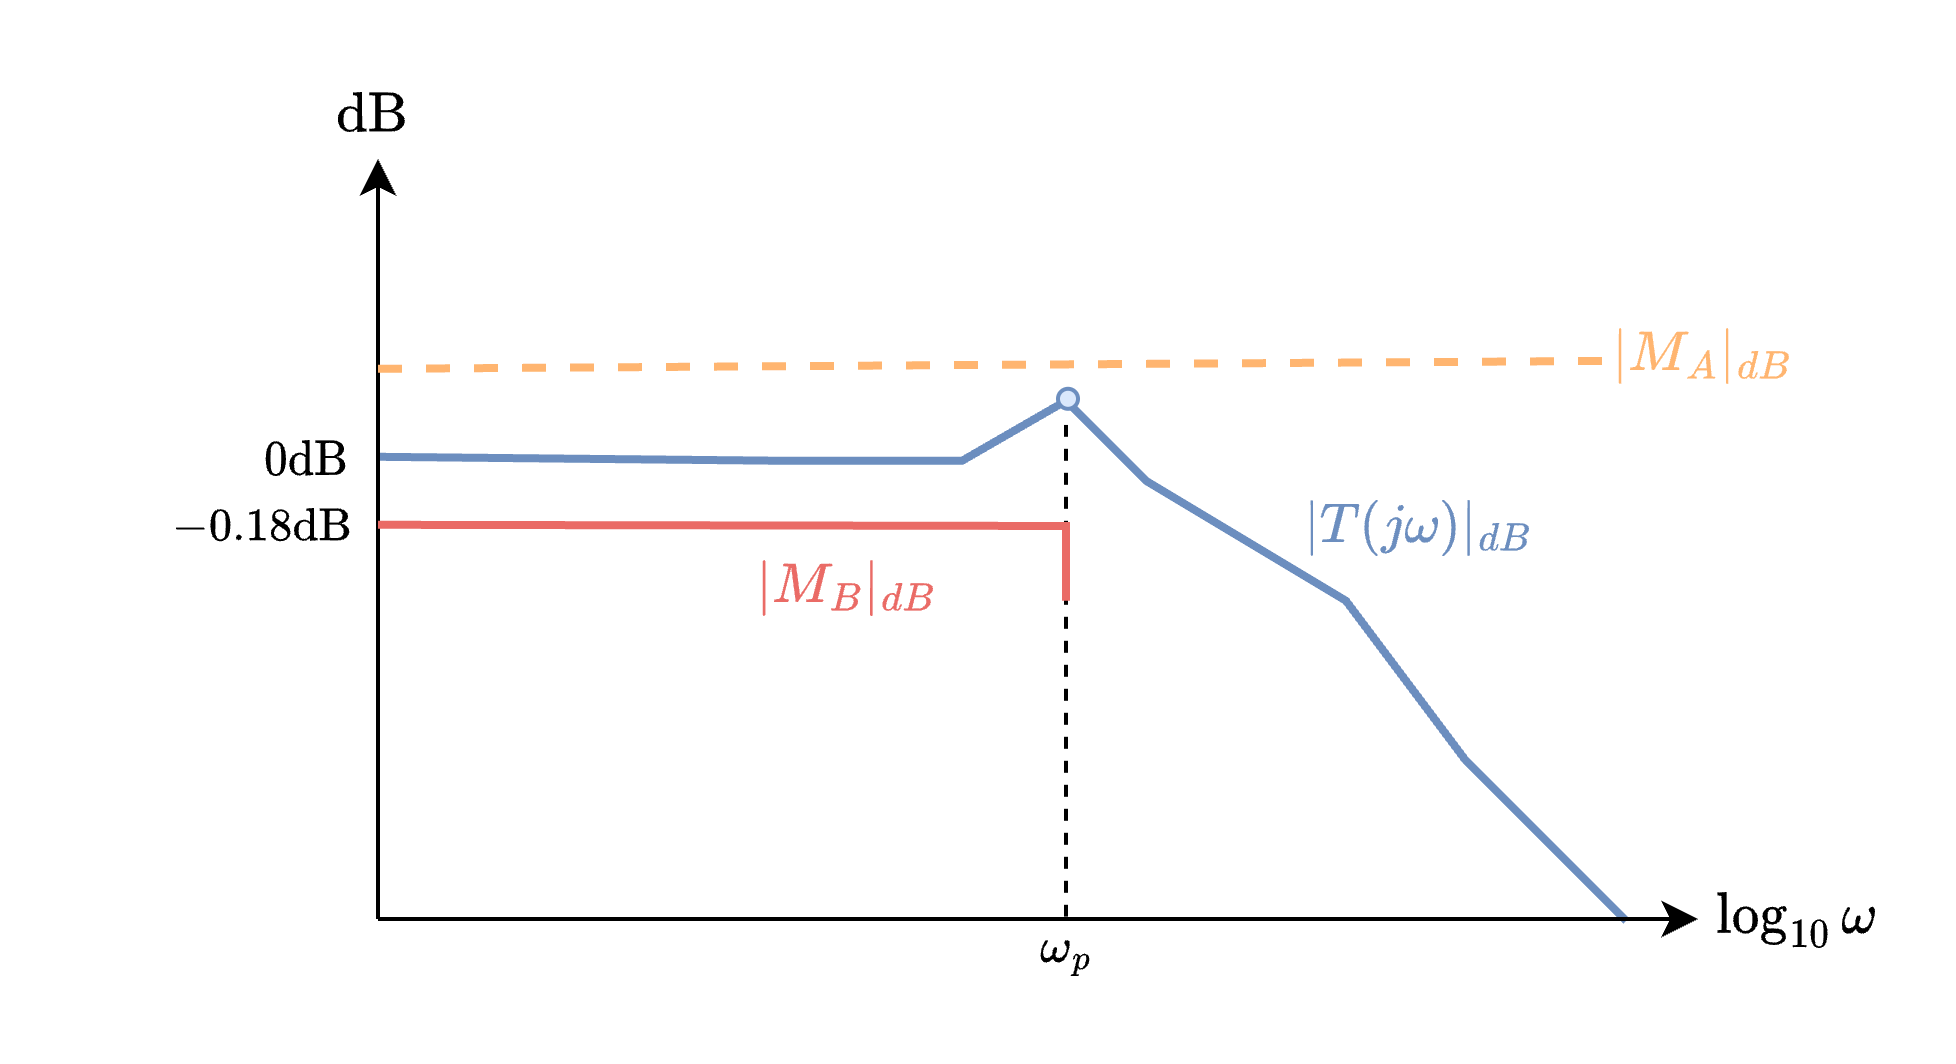

**Figure 10.2:** Above and below bounds enforced for magnitude response of closed-loop system.

The all-frequency *stay-below *bound is calculated using

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}$,

which we previously determined as the peak magnitude response of a second-order low-pass filter, as shown in Figure 10.3.

**Figure 10.3:** Magnitude response of a second-order underdamped system. 

If a percentage overshoot specification, $\%OS$, is given, then we can use


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$$


and then substitute the resulting $\zeta$ into the previous equation to determine $M_A$, which sets the stay-below boundary.

Owing to the fact that a PI controller resembles that of a P controller of the form $G(s)\approx K$ at sufficiently high frequencies ($\omega\geq \frac{10}{T_i}$), we can begin by designing our controller under the assumption that it is simply a proportional controller. One way of doing this is to initially set the integral time constant, $T_i$, to a sufficiently large number, thereby making the zero frequency, $|z|$, very low. We can then design $G(s)\approx K$ in order to meet the required stability and/or transient tracking requirements. Once we have met those requirements, we can then begin to decrease $T_i$. Importantly, we still need $T_i$ to be sufficiently small, otherwise the integral action will take a very long time to reduce the tracking error to zero. On the other hand, very small $T_i$ values results in increased phase lag across a wider frequency range, which makes satisfying stability conditions more tricky. We therefore want a small enough $T_i$ value that also does not interfere with the tracking and stability design specifications.

In order to ensure that $\left|T(j\omega)\right|$ approaches unity as $\omega\rightarrow 0$, we set our *stay-above *bandwidth constraint such that the lower bound represents $\left|T(j\omega)\right|\approx 1$ for the desired frequency bandwidth. In order to not be too overly constraining on the closed-loop gain, we use a lower bound magnitude of $M_B=0.98$ (or approximately $-0.18$ dB) with a frequency range of $\omega\leq \omega_p$, where $\omega_p$ is the peak frequency of a second-order system (see Figure 10.3), which we previously defined as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}$.

The *stay-above* boundary can be seen in Figure 10.2. Note that the choice of $M_B=0.98$ is largely heuristic — we can choose a range of values sufficiently close to (but also less than) unity. 

Once we have defined $\{M_A,M_B\}$, the bounds on $\left|T(j\omega)\right|$ can be converted to bounds on $\left|L(j\omega)\right|$ using the procedure detailed in **Chapter 11** of [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town).

### 10.4.2 Proportional-plus-derivative control design

#### 10.4.2.1 Definition

The PD controller is given by 

$G(s)=K\frac{1+s/\alpha}{1+s/\beta}$,

where $\alpha$ and $\beta$ is the sole zero and pole of $G(s)$, respectively, and $K$ is the DC gain, based on

$G_{dc}=\lim_{s\rightarrow 0}G(s)=K$.

Similarly, the high-frequency gain of $G(s)$ is determined by

$G_{hf}=\lim_{s\rightarrow \infty}G(s)=K\frac{\beta}{\alpha}$.

We also require that $\alpha<\beta$.

#### 10.4.2.2 Design methodology

When defining suitable tracking boundaries in the frequency domain from time-domain specifications, namely $M_B\leq |T(j\omega)|\leq M_A$, we can make use of the approach previously outlined for proportional-plus-integral controllers. Recall that we define $M_A$ as 


$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}},$$


where the damping ratio is obtained from the overshoot specification using

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}$.

As with the PI control design, we specified the *stay-above *constraint as $M_B=0.98,~\forall \omega\leq\omega_p$, where 

$\omega_p=\omega_n\sqrt{1-2\zeta^2}$,

and 

$\omega_n=\frac{4}{\zeta T_s}$,

using the same $\zeta$ from the *stay-below *constraint. 

Using $M_B=0.98,~\forall \omega\leq\omega_p$ is quite convenient, as we expect $\omega_p$ to be the approximate frequency that results in the peak response of $|T(j\omega)|$, which implies that $L(j\omega_p)$ is going to end up being (approximately) the closest point to the overshoot boundary from $|T(j\omega)|\leq M_A$. By this logic, $\omega_p$ is likely to require the greatest phase lead when meeting overshoot requirements, which suggests that $\omega_{max}=\omega_p$ is a suitable choice.

Following the boundary formulation, we begin the design by first setting $\alpha=\beta$, which effectively converts our lead controller into a proportional controller based on

$\lim_{\alpha\rightarrow\beta}G(s)=\lim_{\alpha\rightarrow\beta}K\frac{1+s/\alpha}{1+s/\beta}=K$.

We then initiialy set $K=1$ and then identify on the log-polar plot which frequency requires peak phase lead (i.e. $\omega=\omega_{max}$), and what amount of phase is required. As previously defined, the maximum phase response of a lead filter is given by

$\begin{array}{rl}
\phi_{max}
&= 2\tan^{-1}\frac{\omega_{max}}{\alpha}-\frac{\pi}{2}
\end{array}$,

where $\omega_{max}=\sqrt{\alpha\beta}$. We usually choose $\omega_{max}=\omega_p$ as an educated starting guess.

Assuming we can identify the desired amount of phase lead required, $\phi_{max}$, and frequency point which will experience this maximum phase lead, $\omega_{max}$, we can then determine the required zero location, $\alpha$, by rearranging the above equation as

$\alpha=\frac{\omega_{max}}{\tan\left(\frac{\phi_{max}+\pi/2}{2}\right)}$,

where $\phi_{max}$ is measured in radians. Once we have determined $\alpha$, we can then determine the pole location using

$\beta=\frac{\omega_{max}^2}{\alpha}$.

We should also be cognizant of the fact that at $\omega_{max}$ there will also be a gain increase, so the frequency point that we identify needing phase lead will end up moving both rightwards and upwards in the log-polar plane. As such, we will need to adjust $K$ after updating $\alpha$ and $\beta$ using the equations above.

### 10.4.3 Proportional-integral-derivative control design

#### 10.4.2.1 Definition

The PID controller is given by 

$G(s)=K\frac{\left(1+s/\alpha\right)\left(1+T_is\right)}{sT_i\left(1+s/\beta\right)}$,

where $\alpha$ and $\beta$ is the zero and pole of $G(s)$ from the PD component, respectively, $T_i$ is integral time constant, and$K$ is a gain applied at all frequencies. In simple terms, the PID controller can be thought of as a combination of a PD and PI controller.

#### 10.4.2.2 Design methodology

Recall that a PI controller is designed based on first setting $T_i>>K$ and then choosing $K$ based on the fact that the PI controller behaves like a P controller under this condition. Once $K$ is chosen, $T_i$ is then reduced until the frequency response locus approaches the stability bounds. Analogous to this, we can design a PID controller in two stages:

- Stage 1: Set  $T_i>>K$, which implies that $G(s)\approx K\frac{1+s/\alpha}{1+s/\beta}$. Then select $\{K,\alpha,\beta\}$ based on design methodology detailed in Section 10.4.2. 

- Stage 2: After selecting $\{K,\alpha,\beta\}$ that meets design requirements, continually reduce $T_i$ value until stability design boundaries are close to limit (with some minor safety margin). 

## 10.5 Determining orientation error

### 10.5.1 Quaternion-based error formulation

Recall from **Chapter 8** that the orientation error can be derived using rotation matrices or quaternions. When using quaternions, the error quaternion in $\{B\}$ is given by


$$\begin{array}{cc}{^B{\mathbf q}_D} = {^B{\mathbf q}_W} \otimes {^W{\mathbf q}_D},\end{array}$$


which encodes the rotation required to rotate from the current orientation (captured by frame $\{B\}$) to the desired orientation (captured by frame $\{D\}$). Importantly, ${^B{\bf q}_D}$ describes the rotation in $\{B\}$, which means that the exponential coordinates can be extracted and used as part of feedback control strategies.

Given the standard unit quaternion structure, our error quaternion can be written as


$$\begin{array}{cc}{^B{\mathbf q}_D} =    \left[\begin{array}{cc}    \cos{\frac{\alpha_e}{2}} \\ \sin{\frac{\alpha_e}{2}} {^B\hat{\bf v}_e}     \\ \end{array}\right],\end{array}$$


where $\alpha_e$ corresponds to the rotation angle required to correct the orientation of the robot, and  $^B\hat{\bf v}_e$ refers to the rotation axis. Combined, the corresponding orientation error in $\{B\}$ is given by


$${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}_e,$$


which gives a direct quantification of the amount of rotation required in each channel in order to reorient the rigid body as required. We will make use of this result in the following subsections. Note that we could also use the rotation matrix formulation to extract the same exponential coordinates. However, the quaternion approach is more computationally efficient and remains the approach of choice.

The error vector can be used in an attitude control scheme to inform rotational corrections about all three axes. The block diagram structure is shown Figure 10.4.

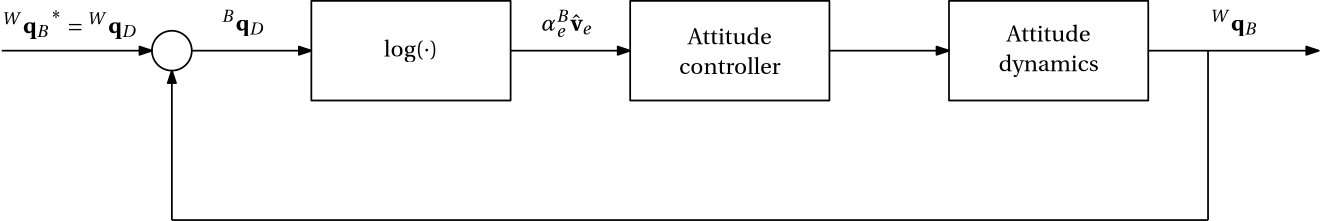

**Figure 10.4:** High-level block diagram of attitude control scheme using quaternion-based orientation error.

### 10.5.2 Thrust vectoring

An alternative approach to determining the orientation error of the quadcopter is to formulate the incremental orientation required in $\{B\}$ based on the direction in which we desire $\hat{\bf z}_B$ to point. Given that $\{D\}$ describes the desired frame, we can then determine the description of $\hat{\bf z}_D$ in $\{B\}$, which is expressed as $^B\hat{\bf z}_D=\hat{\bf z}^*_B$. The incremental orientation required to rotate $\hat{\bf z}_B=[0~~0~~1]^T$ to $^B\hat{\bf z}_D$ is described by


$$\alpha_e{^B\hat{\bf v}}~:~\hat{\bf z}_B\rightarrow {^B\hat{\bf z}_D.$$


Recall from **Chapter 3** that we can determine the exponential coordinates corresponding to the rotational mapping between two (normalised) vectors using the dot and cross product. Based on this, we can determine the exponential coordinates above using


$$\begin{array}{ll}
\alpha_e 
&= \cos^{-1}\left({\hat{\bf z}_B}\cdot {^B\hat{\bf z}_D}\right), 
\end{array}$$



$${^B\hat{\bf v}}=\frac{1}{\sin\alpha_e}\hat{\bf z}_B\times {^B\hat{\bf z}_D},

$$


where


$$\begin{array}{ll}
{^B\hat{\bf z}_D}
&=&{^B{\bf R}_W}{^W{\bf R}_D}{\hat{\bf z}_D},\\
&=&{^B{\bf R}_W}{^W{\bf R}_D}[0~~0~~1]^T.
\end{array}$$


The resulting exponential coordinates, ${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}$, can be used as the tracking error for the quadcopter's roll and pitch controllers. What makes this approach different to that of Section 10.5.1 is that no error is imposed about $\hat{\bf z}_B$ (the yaw channel). This is because the cross product operation above takes in $\hat{\bf z}_B$ as the first argument, meaning that the rotation vector will always be perpendicular to $\hat{\bf z}_B$. This is useful when we do not want to intentionally create motion about $\hat{\bf z}_B$, as exemplified in Section 10.3. For this reason, we will make use of the thrust vectoring approach when deriving our orientation error. 

The block diagram representation of the thrust vectoring orientation control approach is shown in Figure 10.5.

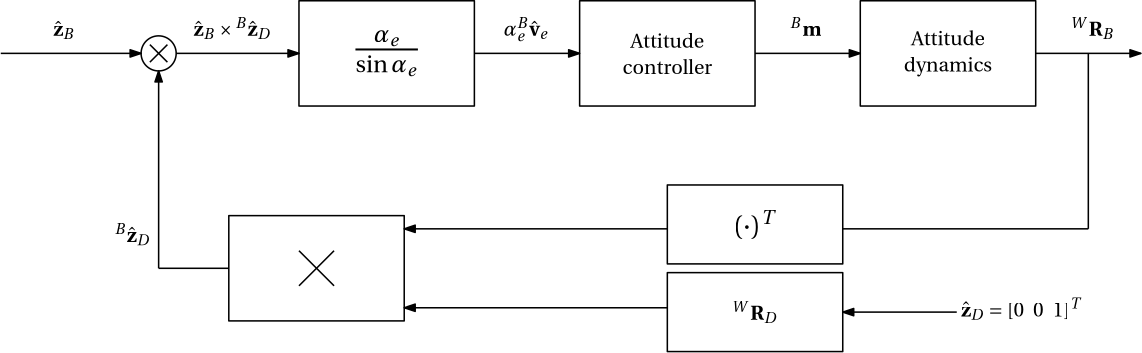

**Figure 10.5:** High-level block diagram of attitude control scheme using thrust vectoring approach.

## 10.6 Attitude control design

### 10.6.1 Decoupled rotational dynamics

With the assumption that $\omega_z\approx 0$, the attitude dynamics simplify to 


$${\bf J}{^B\dot{\bf \omega}}\approx {^B{\bf m}}.$$


Given that $\bf J$ is a diagonal matrix given by


$${\bf J}=\left[\begin{array}{cc}
J_{xx} & 0 & 0 \\
0 & J_{yy} & 0 \\
0 & 0 & J_{zz}
\end{array}\right],$$


attitude dynamics be thought of as three independent rotational systems, which are given by


$$J_{xx}\dot\omega_x \approx m_x,$$



$$J_{yy}\dot\omega_y \approx m_y,$$



$$J_{zz}\dot\omega_z \approx m_z,$$


where $J_{xx}\approx J_{yy}$. We can now proceed to design three independent control laws for the roll, pitch, yaw dynamics presented above. However, we must not forget about the rotor speed model, which is given by


$$\overline\omega_i(s)=\overline\omega_i^*(s)e^{-st_d}.$$


Given that the rotor speeds algebraically relate to the torque vectors, it follows that the desired and applied torque vector relationship is of the form


$${^B{\bf m}(s)={^B{\bf m}^*(s)e^{-st_d}.$$


By extension, the three independent rotational systems above can be described as a function of the desired torque vector as


$$J_{xx}\dot\omega_x(t) \approx m^*_x(t-t_d),$$



$$J_{yy}\dot\omega_y(t) \approx m^*_y(t-t_d),$$



$$J_{zz}\dot\omega_z(t) \approx m^*_z(t-t_d),$$


where $t_d$ indicates the fixed actuation delay, which is common across all four motors.

### 10.6.2 Roll/pitch control design

We will begin by designing the body-frame roll and pitch controllers. Given that $J_{xx}\approx J_{yy}$, the design for both channels will be identical for symmetrical flight operations (when the expectations placed on rotational motion about $\hat{\bf x}_B$ and $\hat{\bf y}_B$ are equivalent. We will therefore perform the design based on information about $\hat{\bf x}_B$ and then use the resulting controller for both body-frame roll and pitch control.

With reference to Section 10.4.1, the roll dynamics in $\{B\}$ are given by


$$J_{xx}\dot\omega_x(t) \approx m^*_x(t-t_d).$$


The system above is linear time-invariant, so we can represent the system in transfer function form as


$$P_{\omega_x}(s)=\frac{\omega_x(s)}{m^*_x(s)}=\frac{1}{J_{xx}s}e^{-st_d},$$


where $m^*_x(s)$ is the input to the open-loop system (representing the desired torque about $\hat{\bf x}_B$) and $\omega_x(s)$ is the corresponding angular velocity output. We are ultimately interested in controlling the orientation of the quadcopter, which requires adaptation of our plant model. While the relationship between the angular velocity in $\{B\}$ and the orientation in $\{W\}$ is naturally nonlinear, we will abstract the body-frame incremental orientation behaviour in a way similar to how we dealt with the translational and rotational control loops of the wheeled robots in **Chapter 8**. It follows that the incremental angular position about $\hat{\bf x}_B$ is given by


$$P_{\Delta\phi}(s)=\frac{\Delta\phi(s)}{m^*_x(s)}=\frac{1}{J_{xx}s^2}e^{-st_d},$$


where $\Delta\phi(s)$ describes the incremental roll angle as a result of integrating the angular velocity about $\hat{\bf x}_B$. Note that our plant model has obtained an additional integrator as a result of relating a moment to an angular position instead of an angular velocity. 

Recalling [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town), the corresponding closed-loop system above will be unstable, as evidenced by the double integrators contributing $180^\circ$ of phase lag at all frequencies, as well as the delay time also contributing phase lag that monotonically increases with frequency. We therefore require a controller that can provide phase lead to stabilise the closed-loop system. Under the assumption that there are no external disturbances acting on our orientation system, we can get away with using a PD controller and rely on the two integrators to provide the sufficient type number to track step and ramp references.

With reference to Section 10.4.2, we can design a PD of the form

$G_{\Delta\phi}(s)=K\frac{1+s/\alpha}{1+s/\beta}$,

for our roll channel if we define a percent overshoot specification, $\%OS$, as well as a settling time requirement, $T_s$. However, if we are expecting any disturbances to act on the roll/pitch channels, such as centripetal coupling, then we would require integral action. This can be facilitated using a PID controller of the form


$$G_{\Delta\phi}(s)=K\frac{\left(1+s/\alpha\right)}{\left(1+s/\beta\right)}\frac{\left(1+T_is\right)}{T_is},$$


which follows the design methodology described in Section 10.4.3. Examples of PD and PID designs are provided below, respectively.

#### Example: PD control design for roll channel

The example below provides the PD design framework for the system 


$$P_{\Delta\phi}(s)=\frac{1}{J_{xx}s^2}e^{-st_d}=\frac{1000}{s^2}e^{-s0.01},$$


where $J_{xx}=1\times10^{-3}$ kgm$^2$ and $t_d=0.01$ seconds. The desired specifications are:

- a desired $2\%$ settling time requirement of $T_s=1$ second and, 

- an allowed percentage overshoot of $\%OS=10\%$.

$M_A$ is determined using


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.5912,$$


OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 )

zeta = 0.5912


$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.0487.$$


Ma = 1/( 2*zeta*sqrt(1-zeta^2) )

Ma = 1.0487

For the *stay-above *boundary we set $M_B=0.98$, and then apply this *stay-above *boundary for all frequencies up until the peak frequency, which is defined as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=\frac{4}{\zeta T_s}\sqrt{1-2\zeta^2}=3.7127$ rad/s.

Ts = 1;
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2)

wp = 3.7127

We then begin by trying to design a P controller of the form $G_{\Delta\phi}(s)=K$, by setting $\alpha=\beta$.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of

$L_{\Delta\phi}(j\omega)=P_{\Delta\phi}(j\omega)G_{\Delta\phi}(j\omega)$. 

Frequency point $\omega=\omega_p$ is also highlighted on the $L_{\Delta\phi}(j\omega)$ locus, as we require all frequencies up to $\omega_p$ to be above the enclosed green region.

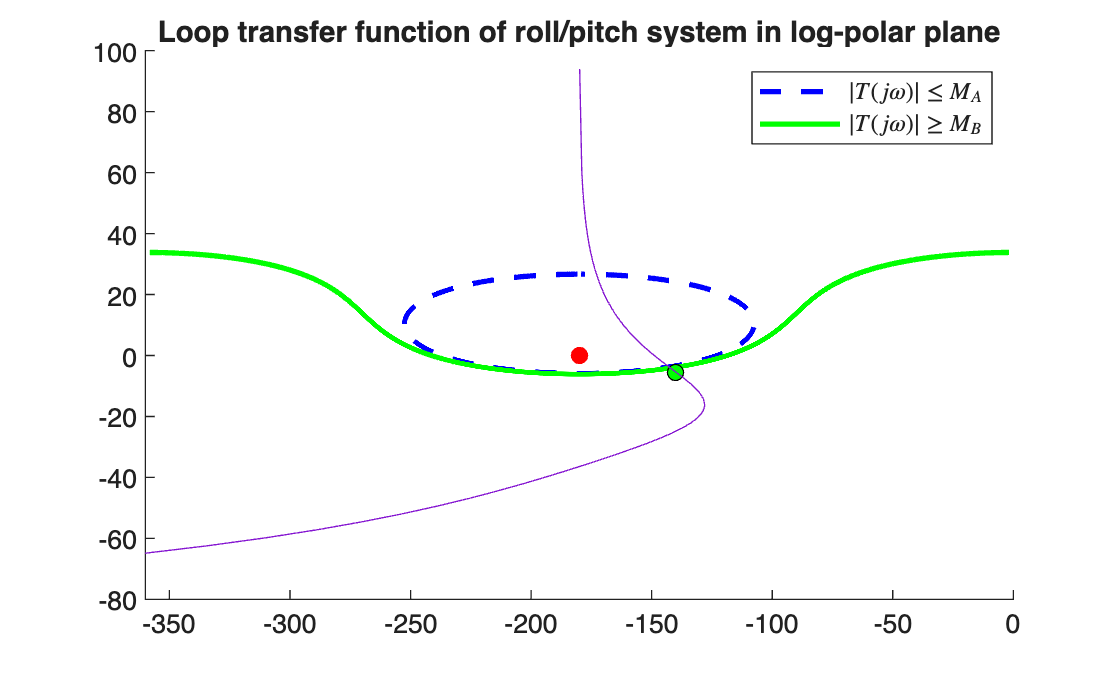

clear
s = tf('s');

P = 1000/(s^2)*exp(-s*.01);
K = 0.005;
alpha = 3.43;
beta = 42;

G = K*(1+s/alpha)/(1+s/beta);
L = P*G;

Ts = 1;
OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

[mag,phase] = nichols(L);
for i=1:length(phase)
    if( phase(i) > 0 )
        phase(i) = phase(i)-360;
    end
end
plot(squeeze(phase),squeeze(20*log10(mag)))
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$',Interpreter="latex")
xlim([-360,0])
title('Loop transfer function of roll/pitch system in log-polar plane')

For $K=0.008$ and $\alpha=\beta$, we see that we are satisfying the (green) $|T(j\omega)|\geq M_B$ requirement, but not the (blue) $|T(j\omega)|\leq M_A$ requirement. We can now make use of our lead filter to provide the much needed phase lead so that we can avoid entering the blue circle. We choose $\omega_{max}=\omega_p$ as the frequency point at which our lead filter will supply the maximum phase lead (owing to the fact that this point will need to move right, and also end up moving upwards from the gain increase), and then measure that we need approximately $80^\circ$, or $\phi_{max}=1.4$ radians, of phase lead in order to get out the circle. 

Using $\omega_{max}=\omega_p=3.7127$ rad/s, we can then determine the required zero location of our controller using

$\alpha=\frac{\omega_{max}}{\tan\left(\frac{\phi_{max}+\pi/2}{2}\right)}$,

as determined using the code below.

w_max = wp;
phi_max = 80*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.3248

beta = w_max^2/alpha

beta = 42.4367

After updating the $\alpha$ and $\beta$ values in the code block above with a gain of $K=0.008$, we see that we violating the *stay-out *boundary. We can either increase our $\omega_{max}$ value to provide phase lead at higher frequencies, or reduce the gain term, $K$. The latter is easiest, and a gain of $K=0.005$ is sufficient to meet both specifications in the frequency domain.

Checking the time-domain step response shows that we meet both user specifications in the time domain too.

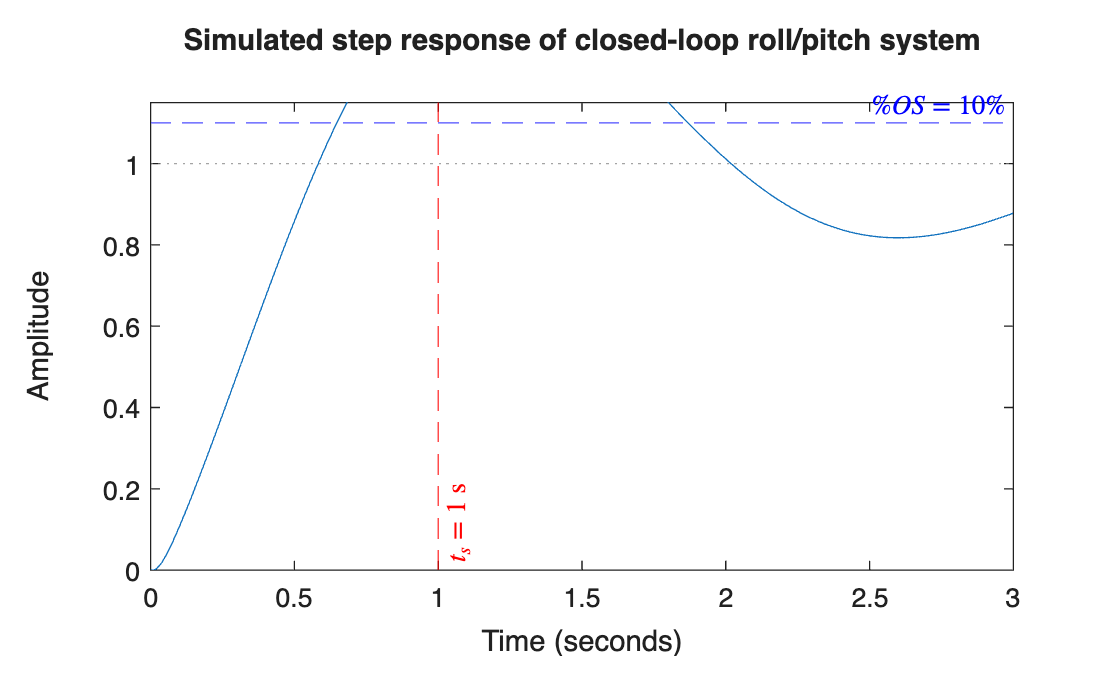

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1+1.5*OS/100])
title('Simulated step response of closed-loop roll/pitch system')

Our designed feedback controller, which is applicable to both the roll and pitch channels, is given by


$$\begin{array}{ll}
G_{\Delta\phi}(s)
&=&K\frac{1+s/\alpha}{1+s/\beta},\\
&=&0.008\frac{1+s/0.325}{1+s/42.44}.
\end{array}$$


#### Example: PID control design for roll channel

We will use the same system from the previous example, namely,


$$P_{\Delta\phi}(s)=\frac{1}{J_{xx}s^2}e^{-st_d}=\frac{1000}{s^2}e^{-s0.01},$$


where $J_{xx}=1\times10^{-3}$ kgm$^2$ and $t_d=0.01$ seconds. The desired specifications are also identical:

- a desired $2\%$ settling time requirement of $T_s=1$ second and, 

- an allowed percentage overshoot of $\%OS=10\%$.

This results in the same design boundaries and design frequency:


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.5912,$$



$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.0487.$$


$\omega_p=\omega_n\sqrt{1-2\zeta^2}=\frac{4}{\zeta T_s}\sqrt{1-2\zeta^2}=3.7127$ rad/s.

According to the design methodology detailed in Section 10.4.3, we first design set $T_i \gg K$ and then the design $G(s)$ as if its a PD controller. We will therefore make use of the solution provided in the previous example to simulate the first design stage where $\{K,\alpha,\beta\}$ is selected.

The code block below allows for design of the PID controller, as well as the necessary visualisation for purposes of synthesis.

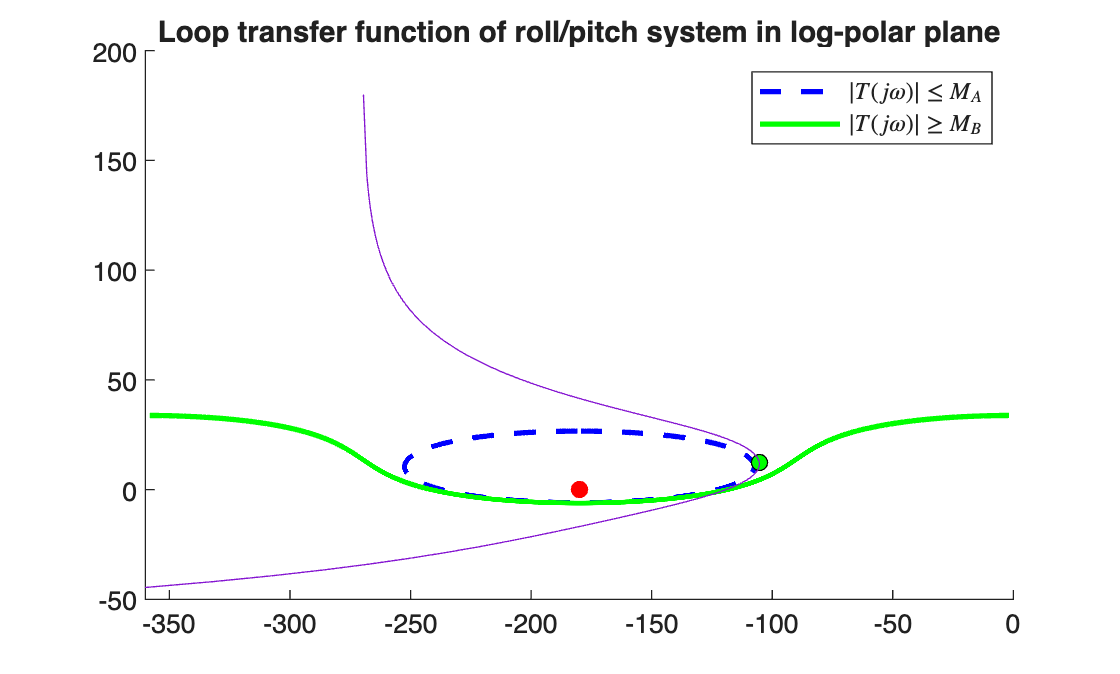

clear
s = tf('s');

P = 1000/(s^2)*exp(-s*.01);
K = 0.005;
alpha = 0.33;
beta = 42;
Ti =5;

G = K*(1+s/alpha)/(1+s/beta)*(1+Ti*s)/(Ti*s);
L = P*G;

Ts = 1;
OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

[mag,phase] = nichols(L);
for i=1:length(phase)
    if( phase(i) > 0 )
        phase(i) = phase(i)-360;
    end
end
plot(squeeze(phase),squeeze(20*log10(mag)))
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$',Interpreter="latex")
xlim([-360,0])
title('Loop transfer function of roll/pitch system in log-polar plane')

With $T_i=100$, for example, our PID controller largely resembles a PD controller, with all boundary conditions met. We can then reduce $T_i$ until we hit a design limit, which is usually the stability boundary. $T_i=5$ suffices to still meet all design boundaries, whilst also sufficiently reducing the integral time constant.

Checking the time-domain step response shows that we meet both user specifications in the time domain too.

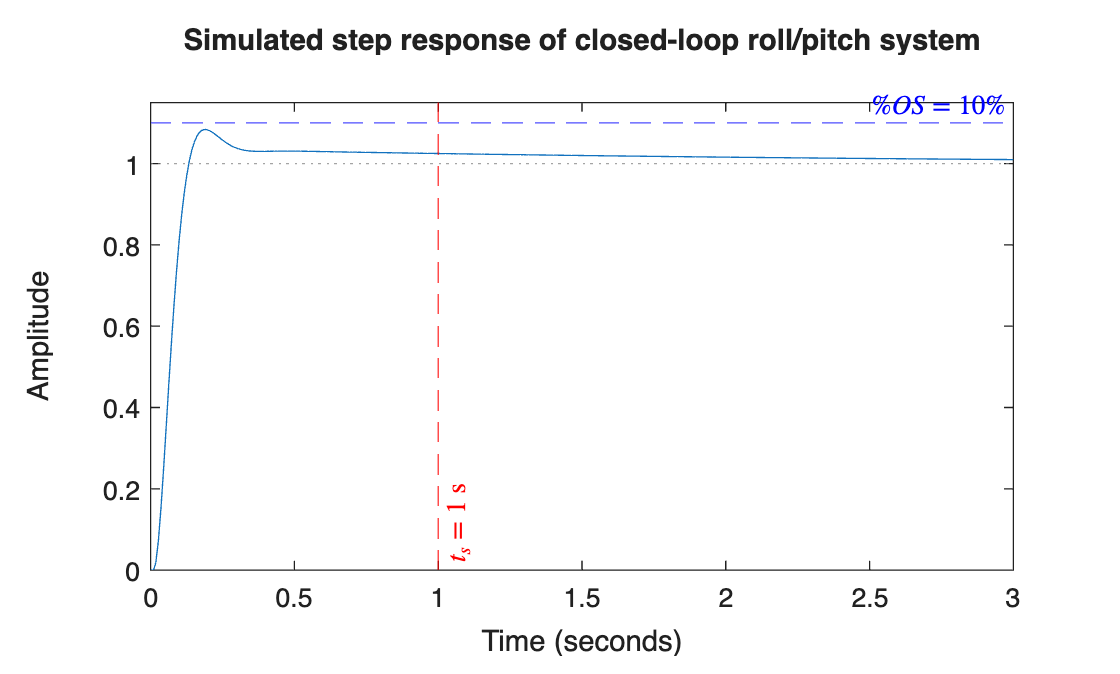

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1+1.5*OS/100])
title('Simulated step response of closed-loop roll/pitch system')

Our designed PID controller, which is applicable to both the roll and pitch channels, is given by


$$\begin{array}{ll}
G_{\Delta\phi}(s)
&=&K\frac{\left(1+s/\alpha\right)}{\left(1+s/\beta\right)}\frac{\left(1+T_is\right)}{T_is},\\
&=&0.005\frac{\left(1+s/0.325\right)}{\left(1+s/42.44\right)}\frac{\left(1+5s\right)}{5s}.
\end{array}$$


Note that in certain cases when designing a PID controller, we may need to update the $\{K,\alpha,\beta\}$ values after choosing $T_i$, as well as the peak frequency value (where the largest phase lead is applied).  

### 10.6.3 Yaw-rate control

As stated in Section 10.3, we need to enforce $\omega_z\approx 0$ in order reap the benefits of the simplified, decoupled attitude dynamics. The yaw dynamics in $\{B\}$ is given by


$$J_{zz}\dot\omega_z(t) \approx m^*_z(t-t_d).$$


The system above is linear time-invariant, so we can represent the system in transfer function form as


$$P_{\omega_z}(s)=\frac{\omega_z(s)}{m^*_z(s)}=\frac{1}{J_{zz}s}e^{-st_d},$$


where $m^*_z(s)$ is the input to the open-loop system (indicating the desired torque about $\hat{\bf z}_B$) and $\omega_z(s)$ is the corresponding angular velocity output. Under the assumption that the yaw controller must act as a regulator (having a zero velocity setpoint), we can design either a P or PI controller, depending on the disturbance requirements. Given that $J_{xx}\approx J_{yy}$ there will be small but non-negligible centripetal coupling on yaw channel, based on Section 10.3, which is described by $\omega_x\omega_y\left(J_{yy}-J_{xx}\right)$. Given this information, and recalling the type number requirements for a control loop with external disturbances, we will require an integrator in our controller in order to reject this effective disturbance fully at steady state. For this reason, we will use a modified version of the PI control design framework from Section 10.4.1, which has the form 


$$G_{\omega_z}(s)=K\frac{1+sT_i}{sT_i}.$$


Specifically, while we should actually be designing the yaw loop based on sensitivity requirements of $|S(j\omega)|\leq \gamma$, we will keep things simple and use the approach outlined in Section 10.4.1, based on the fact that sensitivity and complementary sensitivity are related by


$$S(j\omega)+T(j\omega)=1.$$


As a rule of thumb, we will double the bandwidth of the yaw-rate controller, relative to the roll/pitch controllers, in order to ensure that the term $\omega_x\omega_y\left(J_{yy}-J_{xx}\right)$ does not manifest large $\omega_z$ values, which would in turn result in coupling in the roll and pitch channels for $\{\omega_x,\omega_y\}\neq 0$, based on 


$${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)=\left[\begin{array}{cc}
\omega_y\omega_z\left(J_{zz} -J_{yy} \right) \\
\omega_x \omega_z\left(J_{xx}   -J_{zz} \right) \\
\omega_x \omega_y\left(J_{yy}  -J_{xx} \right) 
\end{array}\right].$$


The design of the yaw-rate PI controller follows based on Section 10.4.1, with an example given below.

#### Example: Yaw-rate PI control design

The example below provides the PI design routine for the yaw-rate system 


$$P_{\omega_z}(s)=\frac{1}{J_{zz}s}e^{-st_d}=\frac{500}{s}e^{-s0.01},$$


where $J_{zz}=0.002$ kgm$^2$ and $t_d=0.01$ seconds. The performance specifications are: 

- a desired $2\%$ settling time requirement of $T_s=0.5$ seconds (based on the bandwidth of the yaw-rate controller needing to be at least twice as high as that of the roll/pitch controllers from the previous example), and 

- an allowed percentage overshoot of $\%OS=10\%$ (we could relax this a bit if need be but we also do not want large overshoot spikes to result in coupling).

$M_A$ is determined using


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.5912,$$


OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 )

zeta = 0.5912


$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.0487.$$


Ma = 1/( 2*zeta*sqrt(1-zeta^2) )

Ma = 1.0487

For the *stay-above *boundary we set $M_B=0.98$, and then apply this *stay-above *boundary for all frequencies up until the peak frequency, which is defined as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=\frac{4}{\zeta T_s}\sqrt{1-2\zeta^2}=7.43$ rad/s.

Ts = 0.5;
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2)

wp = 7.4255

We then begin by trying to design a P controller of the form $G_{\omega_z}(s)=K$, by setting $T_i \gg K$, which makes the PI controller appear like a P controller.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of

$L_{\omega_z}(j\omega)=P_{\omega_z}(j\omega)G_{\omega_z}(j\omega)$. 

Frequency point $\omega=\omega_p$ is also highlighted on the $L_{\omega_z}(j\omega)$ locus, as we require all frequencies up to $\omega_p$ to be above the enclosed green region.

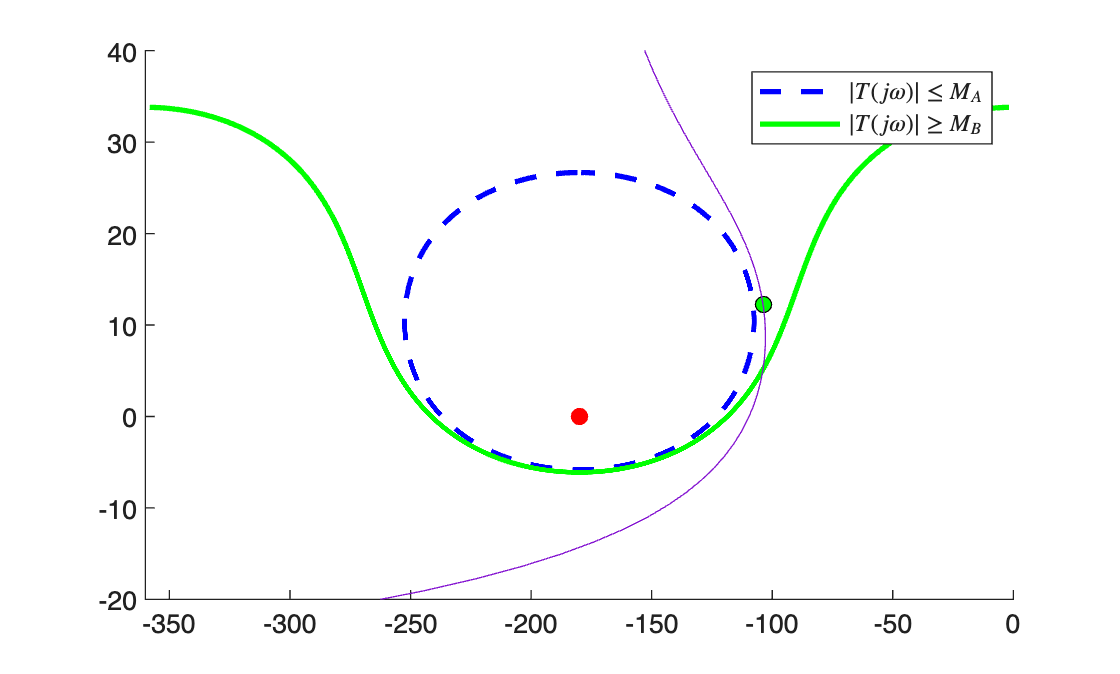

clear
s = tf('s');

P = 500/s*exp(-s*.01);
K = 0.06;
Ti = 0.8;

G = K*(1+s*Ti)/(s*Ti);
L = P*G;

Ts = 0.5;
OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

[mag,phase] = nichols(L,{0.01,500});
for i=1:length(phase)
    if( phase(i) > 0 )
        phase(i) = phase(i)-360;
    end
end
plot(squeeze(phase),squeeze(20*log10(mag)))
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$',Interpreter="latex")
xlim([-360,0]),ylim([-20 40])

Starting with $T_i=100$, we see that a gain of $K=0.06$ is sufficient to meet both specifications. We then incrementally decrease $T_i$ as far as possible until we approach the *stay-out* boundary. A value of $T_i=0.8$ brings the frequency response locus close to the *stay-out *boundary without violating it.

Checking the time-domain step response shows that we meet both user specifications.

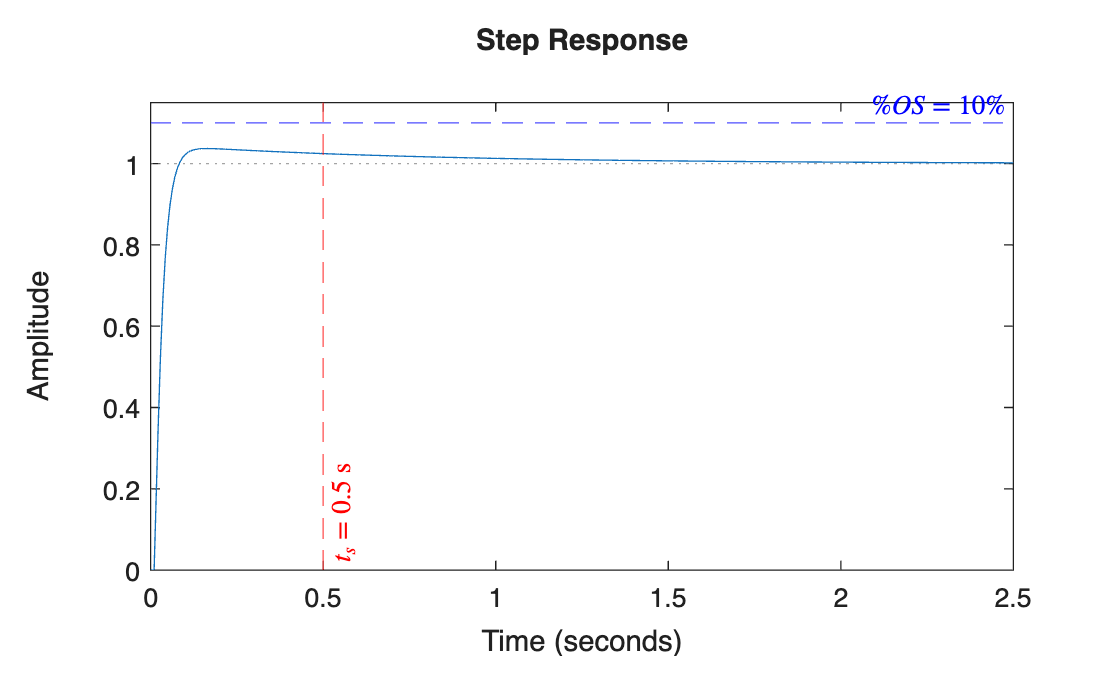

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1+1.5*OS/100])

Our designed yaw-rate feedback controller is given by


$$\begin{array}{ll}
G_{\omega_z}(s)
&=&K\frac{1+sT_i}{sT_i},\\
&=&0.06\frac{1+0.8s}{0.8s}.
\end{array}$$


## 10.7 Implementation of nonlinear control scheme

Following the design of the roll/pitch and yaw controllers, we can integrate all elements and apply for the control solution to the full nonlinear dynamics of the orientation plant. This naturally requires a feedback mechanism, which in this case is facilitated using the thrust vectoring approach outlined in Section 10.5.2. The block diagram in Figure 10.6 describes the nonlinear control scheme when using a yaw-rate PI controller, a roll/pitch PD controller.

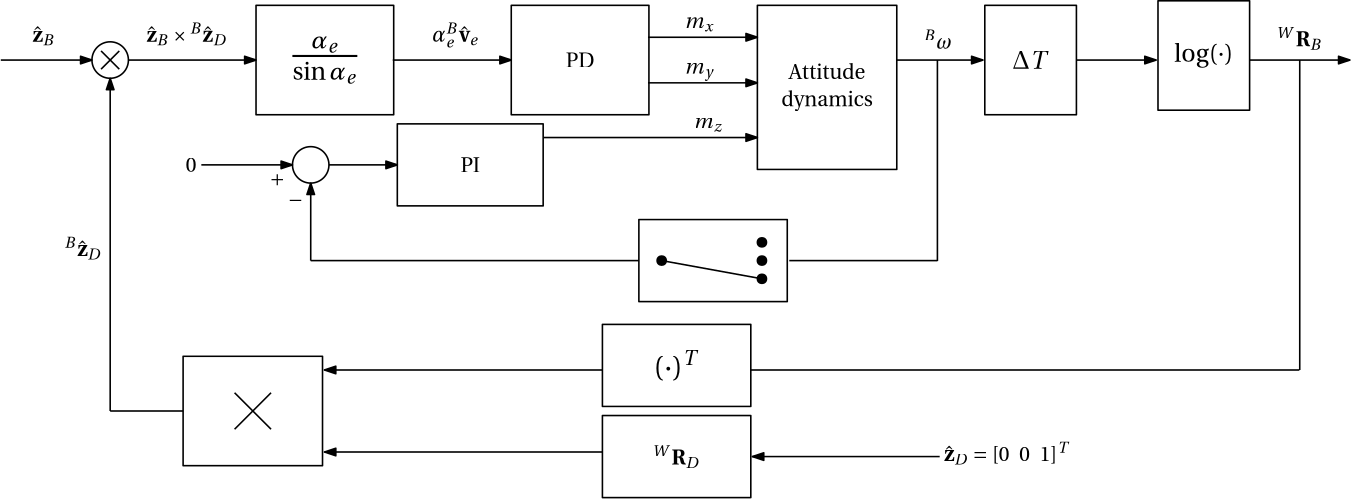

**Figure 10.6:** Attitude control scheme using thrust vectoring.

The control scheme above in theory allows us to specify a direction that we want $\hat{\bf z}_D$ to point towards, namely $^B\hat{\bf z}_D={\hat{\bf z}_B^*}$, which subsequently dictates the orientation change required by the quadcopter to make this possible. While the specification of $^W\hat{\bf z}_D={^W{\bf R}_D}\hat{\bf z}_D$ is currently somewhat arbitrarily, we will ultimately determine this quantity using our translational position controller, which will be covered in **Chapter 11**.

#### Example: Attitude control

The code block below provides a nonlinear 3D simulation of the quadcopter using the yaw-rate PI controller and roll/pitch PD controllers. The controllers are implemented using pseudo-continuous-time difference equations.

You should notice that:

- When $J_{xx}=J_{yy}$, the system behaves as expected, with settling times equivalent to that of the linear simulations.

- When $J_{xx}\neq J_{yy}$, the unmodelled dynamics causes some differences between the linear simulations and nonlinear counterpart, depending on the difference between $J_{xx}$ and $J_{yy}$.

- When $J_{xx}\neq J_{yy}$, centripetal coupling results in a disturbance torque on the yaw channel, which can cause a resulting disturbance torque on the roll/pitch channels. As a result, the PD controller (lacking an integrator) will result in a non-zero steady state error in the short term.

- As the body-frame yaw-rate is being regulated and not the yaw angle, the yaw angle can drift slowly over time when $J_{xx}\neq J_{yy}$. However, this does not affect the direction of the thrust vector.

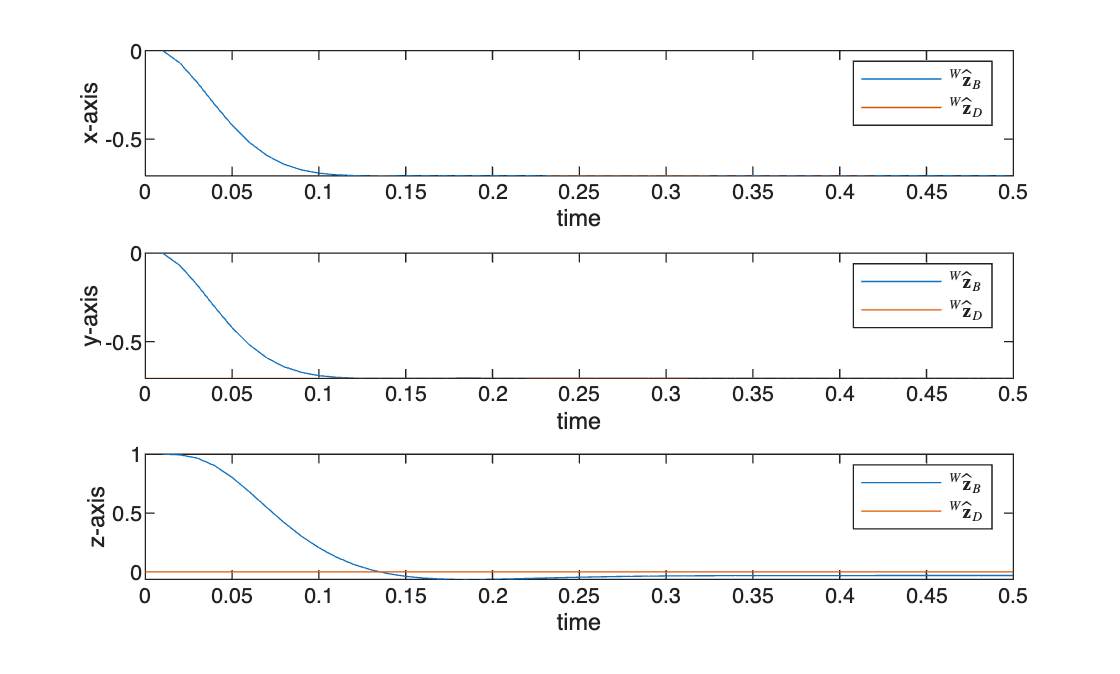

Jxx = 1e-3;
Jyy = 1e-3;
Jzz = 2e-3;
J = diag( [Jxx,Jyy,Jzz] );

dT = 0.01;

%initial conditions
w = [0 0 0]';
q = [1 0 0 0];
u = [0 0 0]';
%desired direction of z axis
z_des = [1 1 0]';
z_des = z_des/norm(z_des);

%desired quaternion
z = [0 0 1]';
n = cross(z,z_des);
alpha = acos( dot(z,z_des));
v = n/sin(alpha);
q_des = [cos(alpha/2) sin(alpha/2)*v'];
R_des = quat2rotm(q_des);

e_past = zeros(3,1);
u_past = zeros(3,1);
desiredMotorSpeeds_past = zeros(4,1);
u_dot = zeros(3,1);
e_dot = zeros(3,1);
w_dot = zeros(3,1);

kf = 1e-5;
kt = 1e-8;
l = 0.1;

A = [kf    kf   kf   kf;
     0  -l*kf    0 l*kf;
     -l*kf  0 l*kf    0;
     kt   -kt   kt  -kt];

invA = inv(A);

q_array = [];
time = [];

for i=1:0.5/dT
    %orientation error
    R = quat2rotm(q);
    z = [0 0 1]';
    z_des = R'*R_des*[0 0 1]';
    n = cross(z,z_des);    
    alpha_e = acos( dot(z,z_des));    
    v_e = n/sin(alpha_e); 
    e = alpha_e * v_e;

    %derivatives
    e_dot = (e-e_past)/dT;

    %roll/pitch PD controller
    K = 0.005;
    a = 0.33;
    b = 42;

    u_dot(1) = -b*u(1)+b*K*e(1)+b*K/a*e_dot(1);
    u(1) = u(1)+dT*u_dot(1);
    u_dot(2) = -b*u(2)+b*K*e(2)+b*K/a*e_dot(2);
    u(2) = u(2)+dT*u_dot(2);

    %yaw PI controller
    K = 0.06;
    Ti = 0.8;

    u_dot(3) = K/Ti*(-w(3))+K*(-w_dot(3));
    u(3) = u(3)+dT*u_dot(3);

    %control allocation
    desiredMotorSpeeds = invA*[0; u];
    %dynamics
    motorSpeeds = desiredMotorSpeeds_past;
    m = A(2:4,:)*motorSpeeds;

    w_dot = J\( m-cross(w,J*w) );
    w = w+dT*w_dot;

    alpha = norm(w)*dT;
    if( alpha==0 )
        v = [0 0 0]';
    else
        v = w/norm(w);
    end
    dq = [cos(alpha/2) sin(alpha/2)*v'];
    q = quatmultiply(q,dq);
    q = q/norm(q);

    %update past state
    e_past = e;
    desiredMotorSpeeds_past = desiredMotorSpeeds;

    %plotting
    % if( mod(i,5)==0 )
    %     figure(1),clf
    %     plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
    %     xlim([-2 2]),ylim([-2 2]),zlim([-1 3])
    %     drawnow
    % end

    q_array = [q_array; q];
    time = [time dT*i];
end
%determine zb wrt {w} and zd wrt {w}
z_b2w = quatrotate(q_array,[0 0 1]);
z_d2w = quatrotate(q_des,[0 0 1]);
%plots
figure(3),clf
subplot(3,1,1),plot(time,z_b2w(:,1)),hold on, line([0 0.5],[z_d2w(1) z_d2w(1)])
xlabel('time'),ylabel('x-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")
subplot(3,1,2),plot(time,z_b2w(:,2)),hold on, line([0 0.5],[z_d2w(2) z_d2w(2)])
xlabel('time'),ylabel('y-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")
subplot(3,1,3),plot(time,z_b2w(:,3)),hold on, line([0 0.5],[z_d2w(3) z_d2w(3)])
xlabel('time'),ylabel('z-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")